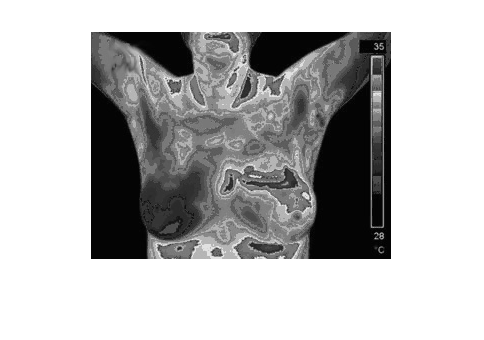

IM = rgb2gray(imread('D:\Sem2\IR\sample.png'));
figure
imshow(IM)

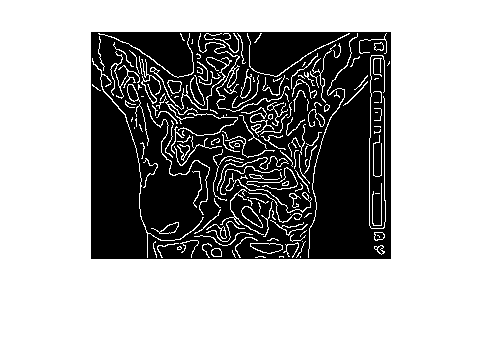


% https://www.mathworks.com/help/images/ref/edge.html
BW = edge(IM, 'canny');

figure
imshow(BW)

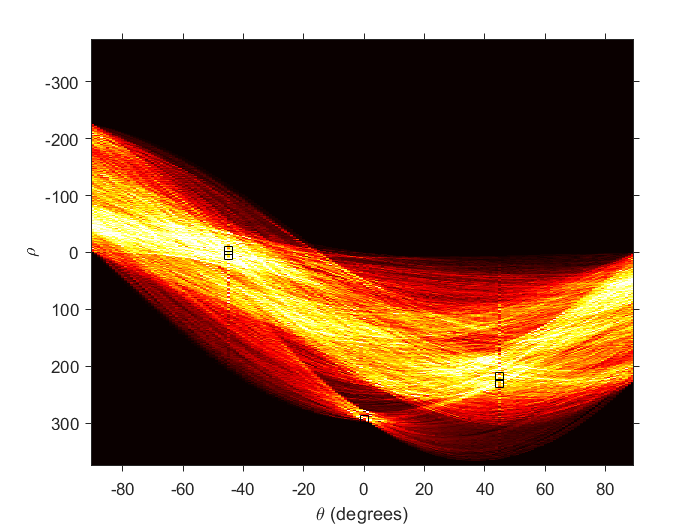


% https://www.mathworks.com/help/images/hough-transform.html
[H,theta,rho] = hough(BW);

figure
imshow(imadjust(rescale(H)),[],...
       'XData',theta,...
       'YData',rho,...
       'InitialMagnification','fit');
xlabel('\theta (degrees)')
ylabel('\rho')
axis on
axis normal 
hold on
colormap(gca,hot)

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));

x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

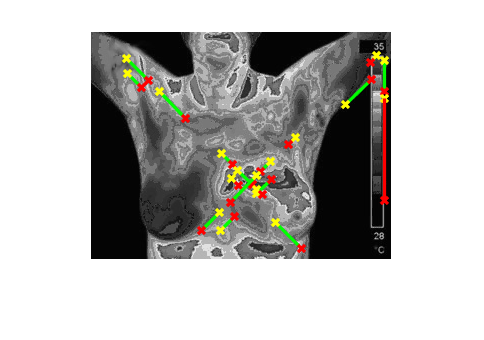


lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',7);

figure, imshow(IM), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');


% https://www.mathworks.com/help/stats/skewness.html
S = skewness(H);
display(S);

S =     1.2563    1.2572    1.2782    1.2820    1.2963    1.2942    1.3132    1.2931    1.2916    1.2987    1.2819    1.2880    1.2851    1.2914    1.3080    1.3048    1.3242    1.3190    1.3353    1.3429    1.3340    1.3598    1.3866    1.3991    1.4219    1.4491    1.4216    1.4632    1.4990    1.5258    1.5269    1.5356    1.5365    1.5370    1.5384    1.5891    1.5637    1.5964    1.5586    1.5891    1.5982    1.5989    1.5958    1.6033    1.5652    2.0576    1.5938    1.5875    1.5683    1.5714


% https://www.mathworks.com/help/stats/kurtosis.html
K = kurtosis(H);
display(K)

K =     3.1012    3.1342    3.2354    3.2367    3.3189    3.3123    3.3893    3.2795    3.2921    3.3230    3.2189    3.2498    3.2322    3.2435    3.3303    3.2856    3.3807    3.3396    3.4084    3.4246    3.3609    3.4594    3.5913    3.6160    3.7239    3.8575    3.6934    3.8809    4.0749    4.2058    4.2091    4.2129    4.2071    4.2159    4.2033    4.5263    4.3112    4.5150    4.2945    4.4474    4.5108    4.4920    4.4692    4.4885    4.2938    6.9547    4.4902    4.5046    4.3879    4.4357
